%RE_CS_221021_F_RadiatorCalculator.mlx
%Documento propiedad del ISC FS Racing Team, dpt. de Refrigeración, para el
%proyecto de coche eléctrico. Presente temporada: IFS-05.

%HERRAMIENTA DE PREDICCIÓN ANALÍTICA ESTÁTICA DE RADIADORES:
%OBJETIVO:
%Deducir las temperaturas de operación del líquido refrigerante (agua),
%dado un radiador. Empleado para deducir la viablidad del radiador, pues es
%lo que limita la normativa. Debería hacerse una correlación con las
%temperaturas internas de los aparatos refrigerados.

%Aparatos refrigerados: Individualmente motor e inversor (EMRAX 228 &
%BAMCOCAR B3).

%PROCEDIMIENTO:
%Datos punto de operación: Dimensiones geométricas rejilla del radiador,
%temperatura entorno, velocidad del aire y calor a disipar.

%Se parten de unas temperaturas iniciales del agua para empezar la
%iteración. Cuanto más cerca del las temperauras estáticas finales más
%rápido convergerá (puede no converger sin son muy dispares).

%Observaciones: Se obtienen las temperturas en régimen permanente del
%refrigerante. No son las del aparato refrigerado. Deberá estimarse qué
%calor emplear (valor medio corregido, valor máximo) y las condiciones
%aerodinámicas a las que se estudia (valor medio ponderado, máximo, etc).

%ESTRUCTURA:
%Se explica el origen de los datos empleados en cada declaración. La
%explicación de la interpretación geométrica se hace en la formulación de
%cada expresión, según las consecuencias de las suposiciones realizadas.

%CRITERIOS DE VALIDEZ DE OPERACIÓN (NORMATIVA/DATASHEET):
%Temperatura máxima fluido en inversor: 65ºC
%Temperatura máxima fluido entrada motor: 50ºC
clc; clear;

%CONDICIONES CONTORNO
%Estimar y valor el punto de operación del radidor en el que se va a
%evaluar. Incluir descripcción del dato empleado.

%Velocidad aerodinámica:
%Dato velocidad media del coche en m/s.
u_coche_mean=60/3.6;

%Dato factor de ponderación velocidad por pérdida de carga. Sacado de
%ensayos en flujo libre del radiador. Adimensional.
load("RE_CS_220901_AFactorVelocidadCoche.mat");

%Velocidad de aire por el radiador en m/s.
u_air=B*u_coche_mean;
clear B u_coche_mean;

%Caudal de agua:
%Se emplea el dato de caudal recomendado por el datasheet del motor. Se deberá
%hacer un estudio hidrodinámico si se pretende usar valores reales [m^3/s]
Q_wat=8/1000/60;

%Temperatura ambiental del aire:
%Se emplea temperatura media en Barcelona en el mes de agosto. Deberá
%hacerse un estudio del destino de competición. En Cº
T_air_in=27;

%Número de radidores en paralelo:
%Para considerar dos radiadores iguales en paralelo en el sistema evaluado.
%Se considerará el N veces el area de radiador y 1/N veces el caudal agua.
N=2;

%Calor generado a disipar:
%El dato acutal sale del ensayo de rotor bloqueado de 110A. Se supone que
%el calor generado en el ensayo solo ocurren en el inversor. Se aproxima un
%calor total (motor+inversor) por las pérdidas máximas de cada aparato.
%Debe hacerse un ensayo en el coche real para tener buenos resultados.

%Pérdidas máximas en cada aparato, del datasheet [W].
q_MaxlossInverter=2e3;
q_MaxLossMotor=42e3*8e-2;

%Calor generado en el ensayo de rotor bloqueado 110A [W] y factor de
%seguridad empleado.
load("RE_CS_220202_AGeneratedQ.mat");
n_sec=2.4;

%Calor total por la ponderación comentada [W].
q_gen=(n_sec*(q_gen+q_MaxLossMotor*q_gen/q_MaxlossInverter))

q_gen = 5.1451e+03

%Por interés, proporción calor del motor frente total.
relation=q_MaxLossMotor/(q_MaxLossMotor+q_MaxlossInverter)

relation = 0.6269

clear n_sec q_MaxLossMotor q_MaxlossInverter relation;

%DATOS DEL RADIADOR EVALUADO:
%Todas las dimensiones dimensionales están en unidades de metros [m]. Los
%datos actuales son considerando los conductor rectangulares. Puede
%afinarse empleando secciones reales y area superficiales.

%Dimensiones de ancho, alto y profundo de los conducto de aire frio.
W_air=240e-3;
H_air=8.5e-3;
L_air=60e-3;
%Número de conductos de aire.
N_air=14;

%Dimensiones de ancho, alto, y largo de los conductos de agua caliente.
W_wat=1.9e-3;
H_wat=58e-3;
L_wat=240e-3;
%Número de conductos de agua.
N_wat=13;

%Datos dimensionales aletas de los tubos, donde el ancho W_fin es el espesor del
%material de la aleta. Se considera la longitud total por su angulación.
W_fin=0.3e-3;
ang_fin=30; %[deg]
H_fin=H_air/(2*cosd(ang_fin));
L_fin=L_air;
%Distancia de separación entre la base de las aletas.
S_fin=1.9e-3;
%Número de aletas en un solo conducto del lado frio de aire. Será el número de 
%aletas reales por dos, para hacer la consideracion de extremo adiabático.
N_fin=2*(340e-3)/S_fin;

%Conductividad térmica del material metálico del radiador. El dato amtual
%empleado en la conductividad de un cobre arbitrario. En [W/m·K]
k_rad=385;

clear ang_fin;

%CÁLCULOS CONSTANTES EN EL CÁLCULO:
%Cálculos hidráulicos del lado caliente del agua:
%Area, perímetro y diámetros hidráulico.
Ah_wat=W_wat*H_wat;
Ph_wat=2*W_wat+2*H_wat;
Dh_wat=4*Ah_wat/Ph_wat;

%Area convectiva de intercambio para el lado de agua caliente. Se han de
%considerar ambos radiadores y cada conducto de agua en el radiador.
Acon_wat=N*N_wat*Ph_wat*L_wat;

%Velocidad de agua por los conductos.
u_wat=Q_wat/(N*Ah_wat*N_wat);

%Cálculos hidráulicos del lado frio del aire:
%Area, perímetro y diámetro hidráulico.
Ah_air=W_air*H_air;
Ph_air=2*W_air+2*H_air;
Dh_air=4*Ah_air/Ph_air;

%Area convectiva de intercambio para el lado del aire frio.
Acon_air=N*N_air*Ph_air*L_air;

%CARGA DATOS HIPÓTESIS INICIAL
%Para inciar el proceso iterativo. Conviene que sean los más cercanos al
%resultado esperado. Valor inverosímiles pueden dar lugar a errores.
%Temperatuas del lado de agua y superficial del radiador.
T_wat_in=40;
T_wat_out=35;
T_sup=37;

%PROCESO REITERATIVO
%Ejecutar hasta la convergencia de los datos. Se puede mirar cualquier
%valor, como la evaluación del Reynolds del agua. Si se quiere reiniciar la
%iteración es necesario ejecutar "CARGA DATOS HIPÓTESIS INICIAL".

%LADO DEL AGUA CALIENTE
%Propiedades del agua según temperatura media.
T_wat_eval=(T_wat_in+T_wat_out)/2;
[ro_wat,cp_wat,mu_wat,k_wat,Pr_wat]=fwat_prop(T_wat_eval);

%Evaluación del número de Reynolds en el lado del agua.
Re_wat=ro_wat*u_wat*Dh_wat/mu_wat

Re_wat = 332.5214

%Se supone que el Reynolds obtenido corresponde con flujo LAMINAR. Deberá
%modificarse el código en caso contrario. Recordar el valor crítico 2300.

%Evaluación del número de Nusselt. Según proporción geométrica del
%conducto. Valor de la tabla formulario de Tranmisión de Calor.
H_wat/W_wat

ans = 30.5263

Nub_wat=5.6;

%Correción de Nusselt. Factor de correción según promptuario. Se emplea la
%viscosidad del agua a temperatura supercial del radiador.
n_wat=-0.11;
[~,~,mu_wat_sup,~,~]=fwat_prop(T_sup);
Nu_wat=Nub_wat*((mu_wat_sup/mu_wat)^n_wat)

Nu_wat = 5.4705


%Coeficiente de convección medio en el agua.
h_wat=Nu_wat*k_wat/Dh_wat

h_wat = 964.6730


%Resistencia térmica del lado de agua caliente.
Rt_wat=1/(h_wat*Acon_wat)

Rt_wat = 0.0014



%LADO DEL AIRE FRIO
%Evaluación propiedades del aire. Se considera como placa plana con aletas,
%por lo que la temperatura de evaluación de propiedades es la media entre
%aire de entrada y temperatura supercial del radiador.
T_air_eval=(T_air_in+T_sup)/2;
[ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);

%Evaluación del número de Reynolds en el lado del aire.
Re_air=ro_air*u_air*L_air/mu_air

Re_air = 3.7664e+04


%Se supone que el valor de Reynolds obtenido corresponde con flujo laminar.
%Se considera Reynolds crítico 5.5e5, por ser placa plana. Se prefiere el
%valor crítico menor pues se espera un flujo con tendencia turbulenta.

%Evaluación del número de Nusselt para placa plana a temperatura constante.
Nu_air=0.6774*(Re_air^0.5)*(Pr_air^(1/3))/((1+((0.0468/Pr_wat)^2/3))^0.25)

Nu_air = 118.2034


%Coeficiente de convección en el lado del aire.
h_air=Nu_air*k_air/L_air

h_air = 51.6572


%Resistencia térmica del lado del aire, sin aletas.
Rt_air=1/(h_air*Acon_air)

Rt_air = 0.0232


%Cálculo rendimientos de las aletas
%Aletas de sección recta. Se parten por la mitad para condición de extremo
%adiabático. Según promptuario de calor.

%Area convectiva de la aleta. Se incluye el area del extremo.
A_fin=2*H_fin*L_fin+L_fin*W_fin;
%Area conductiva de aleta
Ak_fin=W_fin*L_fin;
%Area de base total libre convectiva
A_base=Acon_air-N*N_fin*Ak_fin*N_air;
%Area total convectiva
At_fin=N*N_air*N_fin*A_fin+A_base;

%Cálculo del rendimiento de la aleta y rendimiento total
m_fin=sqrt(h_air*ro_air/(k_rad*Ak_fin));
nu_fin=tanh(m_fin*H_fin)/(m_fin*H_fin);
nut_fin=1-N_air*N_fin*A_fin*(1-nu_fin)/At_fin;

%Resistencia térmica para el lado del aire, con aletas
Rt_air=1/(h_air*At_fin*nut_fin)

Rt_air = 0.0030



%LADO DEL ENTREHIERRO:
%Area conductiva del material del radiador. Se considera el mismo area
%convectiva sin aletas del lado del aire (cantidad conductos de agua).
Ak_cop=N*N_wat*2*W_air*L_air

Ak_cop = 0.7488


%Resistencia térmica del entrehierro.
Rt_cop=W_fin/(k_rad*Ak_cop)

Rt_cop = 1.0406e-06



%CALCULOS DE INTERCAMBIADOR
%Aunque no sean extremadamente precisas, se prefiere tener en cuenta el
%efecto del flujo cruzado en el radiador a obtener las temperaturas por el
%intercambio separado de cada flujo. Método de rendimiento.

%Coeficiente global de transmitancia térmica.
UA=1/(Rt_air+Rt_wat+Rt_cop);

%Capacidades térmicas de flujos y capacidad térmica máx. y mín.
C_air=(N*N_air*Ah_air*u_air)*ro_air*cp_air;
C_wat=Q_wat*ro_wat*cp_wat/N;
C_min=min(C_air,C_wat);
C_max=max(C_air,C_wat);

%Número de unidades de transferencia térmica y resistencia crítica.
NUT=UA/C_min;
Rc=C_min/C_max;

%Cálculo del rendimiento para un radiador de flujo cruzado, conocidad las
%unidades de transferencia que presenta el radadior evaluado.
E=1-exp((NUT^0.22)*(exp(-Rc*(NUT^0.78))-1)/Rc);

%Calor máximo que se debe poder disipar en un intercambiador infinito,
%según el rendimiento obtenido para el radiador evaluado.
q_max=q_gen/E;

%Temperatura en entrada del agua para que dicho calor máximo posible a
%disipar sea posible, dada la temperatura de entrada del aire fija.
%T_wat_in_1=T_air_in+q_max/C_min
T_wat_in=T_air_in+q_max/C_min

T_wat_in = 63.9622



% -----------------------------------------------------------------------
% -----------------------------------------------------------------------
%DATOS DE SALIDA :
T_wat_in

T_wat_in = 63.9622

T_wat_out=T_wat_in-q_gen/C_wat

T_wat_out = 45.2296

T_air_out=T_air_in+q_gen/C_air

T_air_out = 34.5265

T_sup=T_air_in+q_gen*Rt_air

T_sup = 42.2211

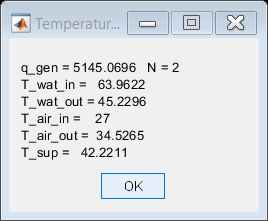


% Close all msgbox instance
hv_figure_all = findall(0, 'Type', 'Figure');
delete( hv_figure_all( arrayfun(@(h) contains(h.Tag, 'Msgbox'), hv_figure_all) ) )

message=[strcat("q_gen = ",num2str(q_gen),"   N = ",num2str(N));
         strcat("T_wat_in =   ",num2str(T_wat_in));
         strcat("T_wat_out = ",num2str(T_wat_out));
         strcat("T_air_in =    ",num2str(T_air_in));
         strcat("T_air_out =  ",num2str(T_air_out));
         strcat("T_sup =   ",num2str(T_sup))];

msgbox(message,"Temperaturas obtenidas");

%RECORDATORIO CRITERIOS DE VALIDEZ DE OPERACIÓN (NORMATIVA/DATASHEET):
%Temperatura máxima fluido en inversor: 65ºC
%Temperatura máxima fluido entrada motor: 50ºC

%SECCIÓN OMITIDA: Cáculo de temperatura por método de diferencia
%logarítmica. Se omite por un factor obtenido de tabla. Posible adición con
%un estudio decente.

%Se hace también el cálculo de temperatura caliente de entrada
%por el método de diferencia de temeperatura logarítmica.
%Constante R y P para deducir el factor de correción F
T_air_out=T_air_in+q_gen/C_air;
R=(T_air_in-T_air_out)/(T_wat_out-T_wat_in)
P=(T_wat_out-T_wat_in)/(T_air_in-T_wat_in)
%Factor de corrección F
F=0.95;

dTl=q_gen/(UA*F)
%Temperatura de entrada caliente según el método de diferencia temperatura
%logarítmica
syms x_in x_out
[T_wat_in_2,~]=vpasolve([dTl==(x_in-T_air_out-x_out+T_air_in)/log((x_in-T_air_out)/(x_out-T_air_in)),q_gen==C_wat*(x_in-x_out)],[x_in,x_out])
T_wat_in_2=double(T_wat_in_2)
T_wat_in=min(T_wat_in_1,T_wat_in_2)
%Conocida la temperatura inicial del lado caliente, el resto de valores se
%deducen facil.



n=1;
filename=['Rad_0' num2str(n) '.txt']
%filename='Radiador antiguo.txt'
link='https://moto.autodoc.es/frigair/8564187';
datos_2save=[T_wat_out;T_wat_in;T_air_out];
datos_3save={datos_2save;link};
writecell(datos_3save,filename);

%Cálculos para caudales de radiadores
%Suponiendo que el ventilador tiene el mismo comportamiento que un caudal
%de aire inpertubado, como el de los ensayos de pérdida de carga en
%radiador. Hará falta un caudal tal que con el factor de pérdida de carga
%la velodidad del aire sea mayor a la cn la que se realizazn los cáluclos
%termicos

%Caudal libre del rventilador propuesto
Q_fan=182.5
Q_fan=Q_fan/60;

%Velocidad, dada la sección de un radiador a usar
u_fan=Q_fan/(Ah_air*N_air*N);
u_fan=u_fan*3.6;

%Ponderaión por factor de pérdida de carga en el radiador
load("RE_CS_220901_AFactorVelocidadCoche.mat");
u_fan=B*u_fan
clear B;

%Factor de seguridad de n=2
n=2;
u_fan=u_fan/n

%Cálculo rápido para la presión de una bomba
%Dada ña presión de las bombas de agua de amazon, expresada en metros de
%altura o elevación, el valor de presión en bares es la sigueinte
p_pump=4.1;
p_pump=p_pump*ro_wat*9.8/100000
%Caudal de la bomba, a expresar en litros por minuto
Q_pump=650;
Q_pump=Q_pump/60;

%Cálculo de la presión en bares, para un caudal de 8l/min. Deberá ser mayor
%a los 0.3bar
p_op_pump=p_pump*(Q_pump-8)/Q_pump